## HMRF-GMM-EM Segmentation

**Author: **Harshit Varma

*(Run this live script cell by cell for testing)*

clear variables;
clc;

Load the given data

DATA_PATH = "../data/data.mat";
data = load(DATA_PATH, "-mat");
img  = data.imageData;
mask = data.imageMask;

Display the data and save as JPG for easier access:

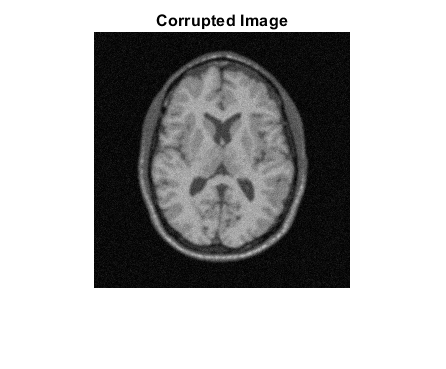

imshow(img);
title("Corrupted Image");
saveas(gcf, "../plots/corrupted.jpg", "jpg");

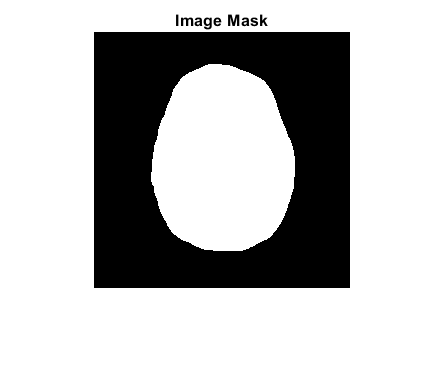


% We only need to segment inside the brain, the background-foreground
% segmentation is already provided by the mask
imshow(mask);
title("Image Mask");
saveas(gcf, "../plots/mask.jpg", "jpg");

% The number of categories for the segmentation (gray matter, white matter and CSF)
k = 3; 

% Get the background (bg) and the foreground (fg) masks
mask_fg = (mask == 1);
mask_bg = (mask == 0);

Set the background values to 0 since we don't need them

This also helps us see the segmentation better

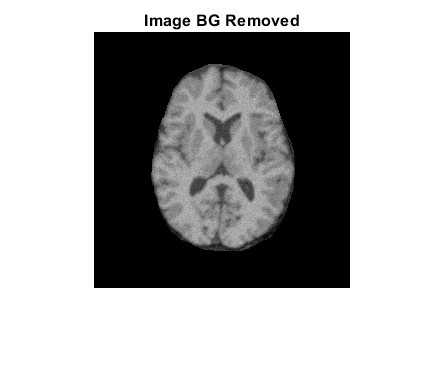

img(mask_bg) = 0;
imshow(img);
title("Image BG Removed");

### **Initial Segmentation using K-Means**

We use the standard K-Means algorithm for obtaining the initial segementation, since it's simple, fast and gives a good quality initial estimate. 

The initial class means and the standard deviation estimates are obtained from the initial label image by computing the sample means and the sample standard deviations for each class.

% Get the inital segmented image using K-Means algorithm
eps = 1e-5;
[seg_init, mu_init, sigma_init] = KMeans(img, mask, k, eps);

K-Means ran for 19 iterations


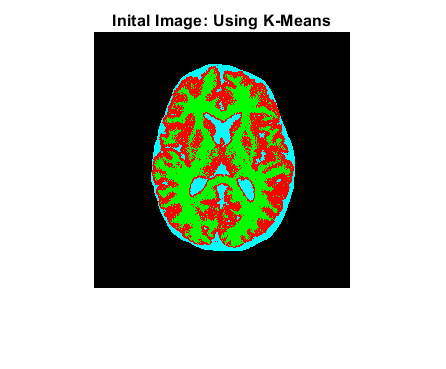


% Show and save the initial segmented image 
showSegmented(seg_init, k, "Inital Image: Using K-Means", "../plots/segment_kmeans.jpg");

As observed, the inital selected means are all near the 3 (local) modes of the histogram

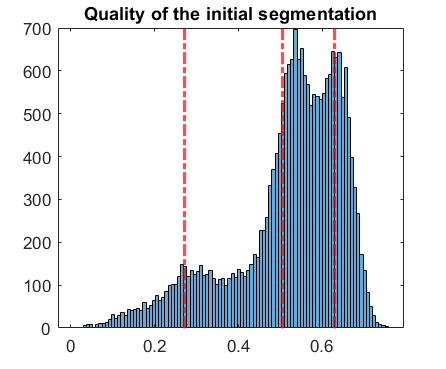

histogram(img(mask_fg), 100);
for i = 1:k
    xline(mu_init(i), "-.r", 'LineWidth', 2);
end
title("Quality of the initial segmentation");

### The EM Algorithm

beta = 0.75; % This gave the best looking results
eps_EM = 1e-7;
N_EM_max = 40; % Specifies the max no. of iterations of EM
N_ICM = 10; % The number of times we run ICM

fprintf("Starting the EM Optimization\n");

Starting the EM Optimization


[seg, memberships, mu, sigma] = EM(seg_init, img, mask, k, mu_init, sigma_init, beta, eps_EM, N_ICM, N_EM_max);

Before: 3.009743e+04 | After: 3.169157e+04
Before: 3.184478e+04 | After: 3.202961e+04
Before: 3.209191e+04 | After: 3.218720e+04
Before: 3.221612e+04 | After: 3.229342e+04
Before: 3.230238e+04 | After: 3.233793e+04
Before: 3.233939e+04 | After: 3.235157e+04
Before: 3.235048e+04 | After: 3.236235e+04
Before: 3.236165e+04 | After: 3.237554e+04
Before: 3.237513e+04 | After: 3.237727e+04
Before: 3.237665e+04 | After: 3.237747e+04
Before: 3.237708e+04 | After: 3.237708e+04


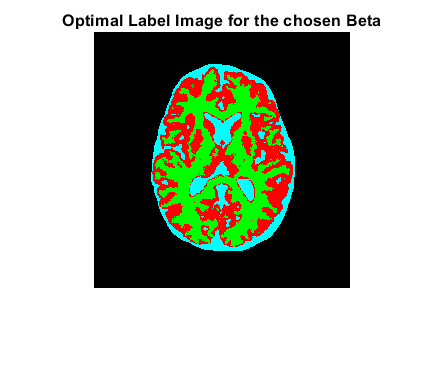

showSegmented(seg, k, "Optimal Label Image for the chosen Beta", "../plots/segment_em.jpg");

The optimal class memberships for the chosen beta

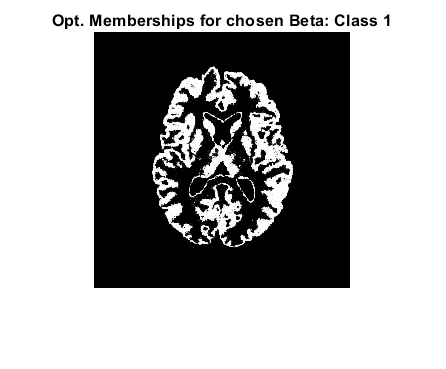

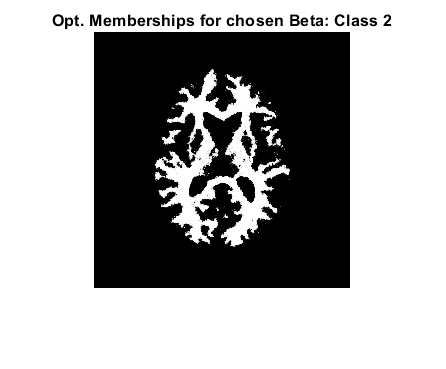

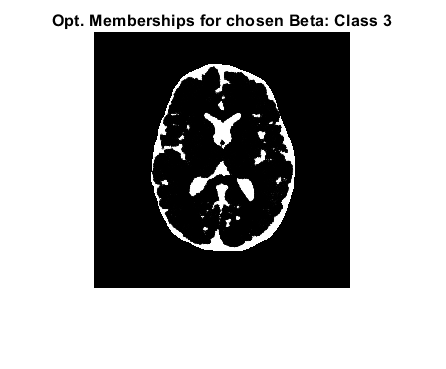

for i = 1:k
    m = memberships(:, :, i);
    figure;
    imshow(m);
    title(sprintf("Opt. Memberships for chosen Beta: Class %d", i));
    saveas(gcf, sprintf("../plots/memberships_%d.jpg", i), "jpg");
end

### Without MRF Prior

beta = 0;
[seg_no_mrf, memberships_no_mrf, mu_no_mrf, sigma_no_mrf] = EM(seg_init, img, mask, k, mu_init, sigma_init, beta, eps_EM, N_ICM, N_EM_max);

Before: 3.592043e+04 | After: 3.632155e+04
Before: 3.641021e+04 | After: 3.656357e+04
Before: 3.651502e+04 | After: 3.660590e+04
Before: 3.653902e+04 | After: 3.659226e+04
Before: 3.650135e+04 | After: 3.653362e+04
Before: 3.643400e+04 | After: 3.645700e+04
Before: 3.636104e+04 | After: 3.637257e+04
Before: 3.628792e+04 | After: 3.629450e+04
Before: 3.622886e+04 | After: 3.623214e+04
Before: 3.618449e+04 | After: 3.618599e+04
Before: 3.615349e+04 | After: 3.615451e+04
Before: 3.613365e+04 | After: 3.613429e+04
Before: 3.612132e+04 | After: 3.612171e+04
Before: 3.611388e+04 | After: 3.611417e+04
Before: 3.610961e+04 | After: 3.610973e+04
Before: 3.610704e+04 | After: 3.610711e+04
Before: 3.610554e+04 | After: 3.610560e+04
Before: 3.610468e+04 | After: 3.610469e+04
Before: 3.610414e+04 | After: 3.610417e+04
Before: 3.610385e+04 | After: 3.610385e+04


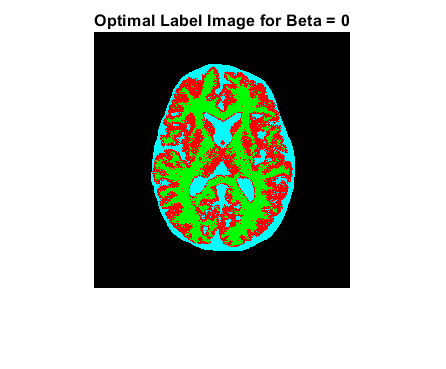

showSegmented(seg_no_mrf, k, "Optimal Label Image for Beta = 0", "../plots/segment_em_no_mrf.jpg");

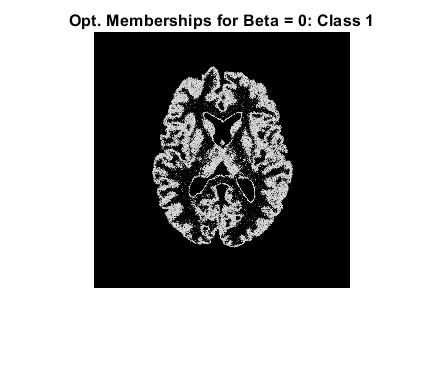

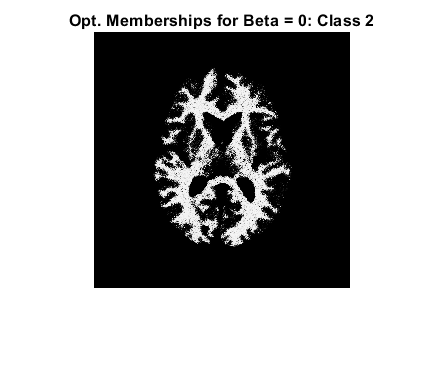

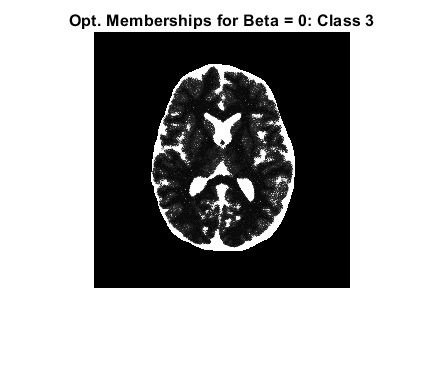

for i = 1:k
    m = memberships_no_mrf(:, :, i);
    figure;
    imshow(m);
    title(sprintf("Opt. Memberships for Beta = 0: Class %d", i));
    saveas(gcf, sprintf("../plots/memberships_no_mrf_%d.jpg", i), "jpg");
end